## merge round 1 and rotate

input_path = fullfile("E:/2020-08-01-mPlac/output/max/");
data_dirs = dir(fullfile(input_path, "tile_*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name);

Ndirs = numel(data_dirs);
upd = textprogressbar(Ndirs, 'updatestep', 1);

Completed [                    ]   0% --:--:--



for p=1:Ndirs
    
    
    curr_data_dir = data_dirs{p};
    curr_path = fullfile(input_path, curr_data_dir, "registered_image", "round1");
    curr_out_path = fullfile(input_path, "round1_merged_rotated");
    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
    
    curr_files = dir(fullfile(curr_path, "*.tif"));
    curr_img = zeros([3072 3072 25 4], 'uint8');
    for i=1:4
        curr_file_path = fullfile(curr_path, curr_files(i).name);
        curr_img(:,:,:,i) = new_LoadMultipageTiff(curr_file_path, 'uint8', 'uint8', false);
    end
    
    
    curr_max = max(curr_img, [], 4);
    curr_max = imrotate(curr_max, -90);
    
    curr_fname = fullfile(curr_out_path, sprintf("%s.tif", curr_data_dir));
    if exist(curr_fname, 'file') == 2
        delete(curr_fname);
    end
    for j=1:25   
        imwrite(curr_max(:,:,j), curr_fname, 'writemode', 'append');        
    end
    
    upd(p);
end

Completed [====================] Done. [569 seconds]


## rotate dots, dapi, nissl

input_path = fullfile("E:/2020-08-01-mPlac/output/max/nissl/");
input_files = dir(fullfile(input_path, "*.tif"));
% input_files = struct2table(input_files);
% input_files = natsort(input_files.name);

Nfiles = numel(input_files);
upd = textprogressbar(Ndirs, 'updatestep', 1);

Completed [                    ]   0% --:--:--


curr_out_path = fullfile("E:/2020-08-01-mPlac/output/max/", "nissl_rotated");
if ~exist(curr_out_path, 'dir')
    mkdir(curr_out_path)
end

for p=1:Nfiles
    curr_file = fullfile(input_path, input_files(p).name);
    curr_img = new_LoadMultipageTiff(curr_file, 'uint8', 'uint8', false);
    curr_img = imrotate(curr_img, -90);
    
    curr_fname = fullfile(curr_out_path, input_files(p).name);
    if exist(curr_fname, 'file') == 2
        delete(curr_fname);
    end
    for j=1:25   
        imwrite(curr_img(:,:,j), curr_fname, 'writemode', 'append');        
    end
    
    upd(p);
end

Completed [====================] Done. [280 seconds]


## plot dapi centroid

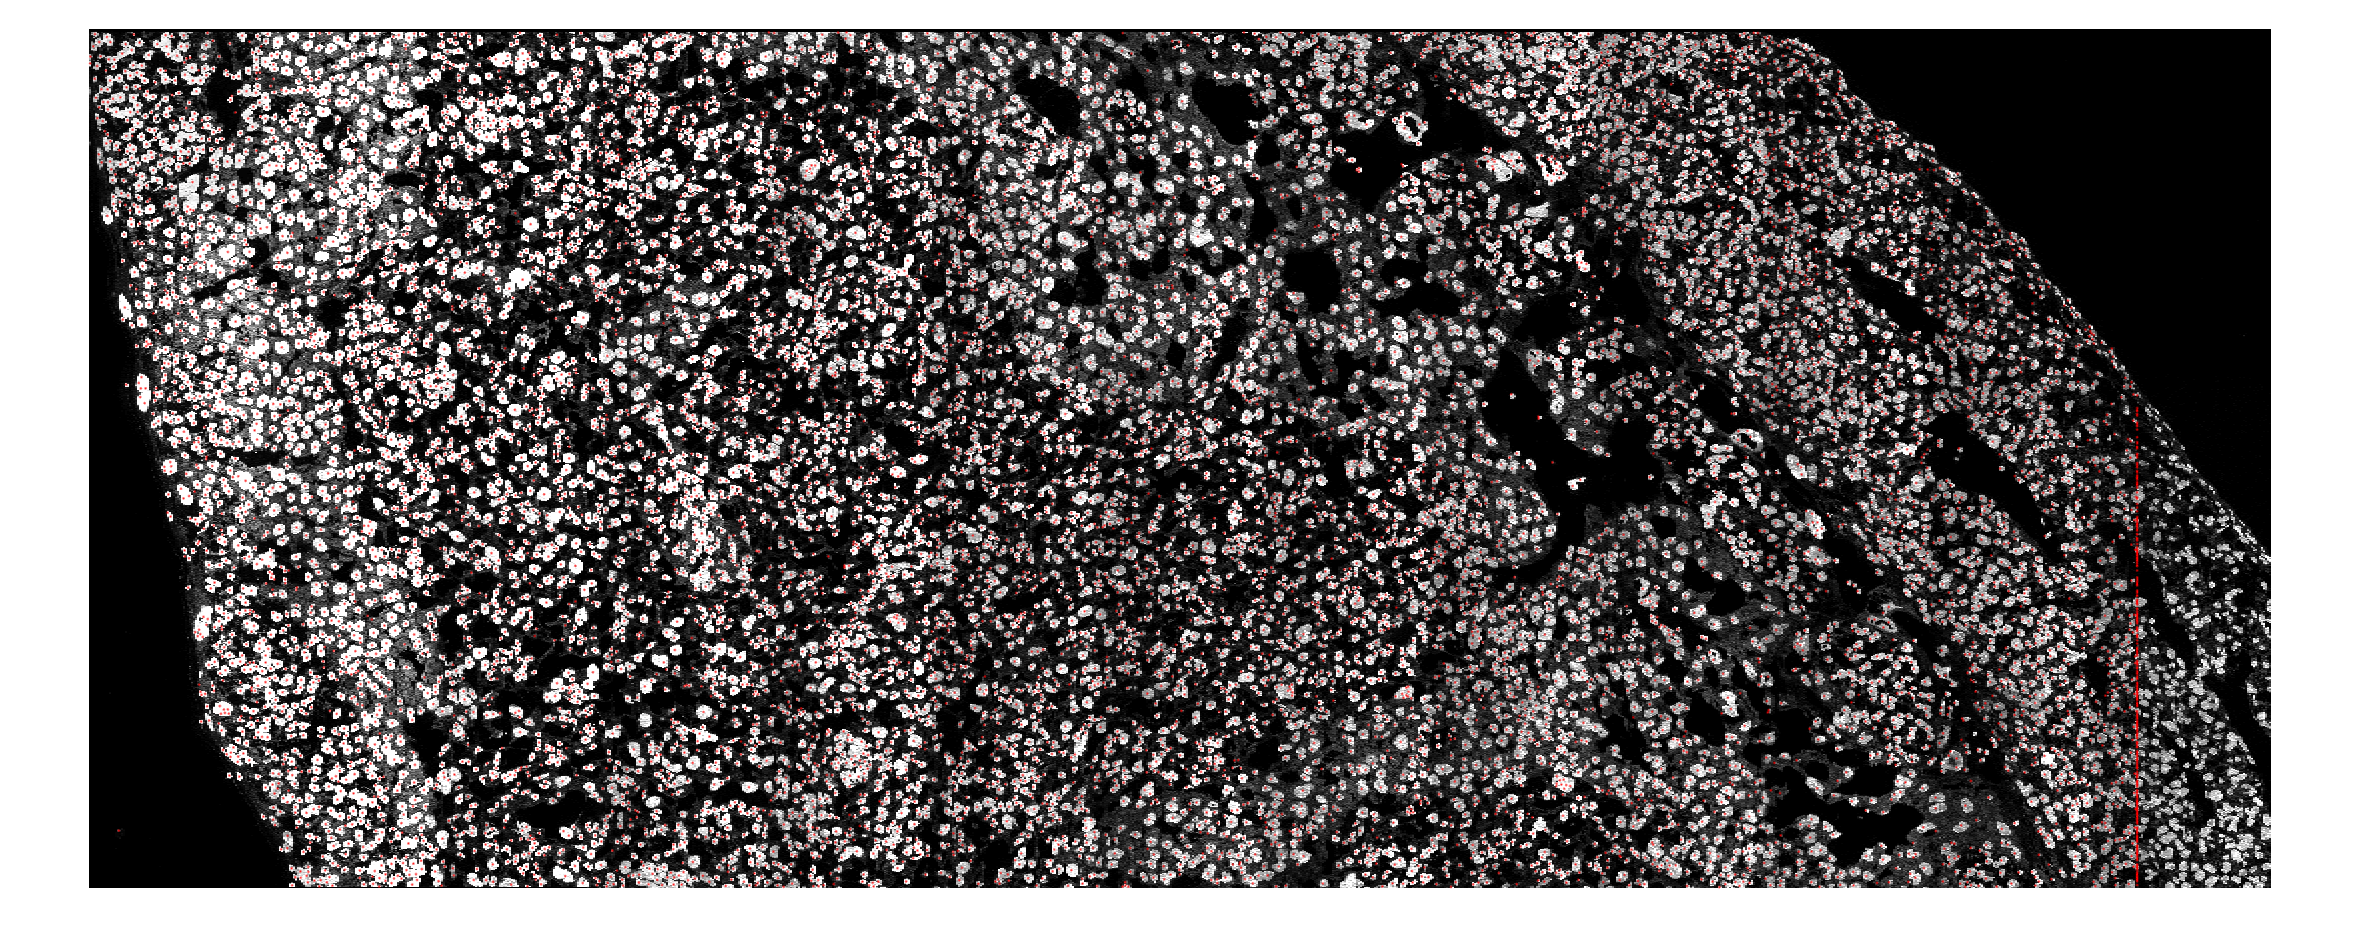

dapi_seg_file = fullfile("E:/2020-08-01-mPlac/output/max/stitched_images/dapi_seg_1_0702.tif");
dapi = imread(dapi_seg_file);

centroid = regionprops(dapi, "Centroid");
centroid = struct2table(centroid);
centroid = int16(centroid.Centroid);

nissl_file = fullfile("E:/2020-08-01-mPlac/output/max/stitched_images/nissl_stitched.tif");
nissl = imread(nissl_file);

plot_centroids(centroid, nissl, 4)

% merge dots 
stitch_file = fullfile("E:/2020-08-01-mPlac/output/max/dapi_rotated/TileConfiguration.txt");
%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [5, Inf];
opts.Delimiter = ["(", ")", ",", ";"];

% Specify column names and types
opts.VariableNames = ["Definetheimagecoordinates", "Var2", "Var3", "VarName4", "VarName5", "VarName6"];
opts.SelectedVariableNames = ["Definetheimagecoordinates", "VarName4", "VarName5", "VarName6"];
opts.VariableTypes = ["double", "string", "string", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, ["Var2", "Var3"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "Var3"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Definetheimagecoordinates", "TrimNonNumeric", true);
opts = setvaropts(opts, "Definetheimagecoordinates", "ThousandsSeparator", ",");

% Import the data
TileConfiguration = readtable(stitch_file, opts);
TileConfiguration.Properties.VariableNames = {'tile' 'x' 'y' 'z'};
TileConfiguration.x = int16(TileConfiguration.x);
TileConfiguration.y = int16(TileConfiguration.y);
head(TileConfiguration, 5)

ans = 5×4 table
    tile      x      y    z
    ____    _____    _    _

      1         0    0    0
      6      2654    0    0
     11      5307    0    0
     16      7962    1    0
     21     10612    1    0



%% Clear temporary variables
clear opts


base_path = fullfile("E:/2020-08-01-mPlac/output/max/");

merged_row_points = {};
merged_row_reads = {};

a = 1;
for r=1:5
    row_points = int32([]);
    row_reads = {};
    for c=1:13
        curr_row = table2cell(TileConfiguration(a, :));
        a = a + 1;
        [tile, x, y, z] = curr_row{:};
        
        curr_dot_file = fullfile(base_path, sprintf("tile_%d", tile), "goodPoints_max3d.mat");
        load(curr_dot_file);
        
        % rotate
        temp = tile_goodSpots;
        tile_goodSpots(:, 2) = temp(:, 1);
        tile_goodSpots(:, 1) = 3073 - temp(:, 2);
        
        
        tile_goodSpots = int32(tile_goodSpots) + int32([x y z]);
        if isempty(row_points)
            % row_points = [row_points; tile_goodSpots];
            % row_reads = [row_reads; tile_goodReads];
            row_points = tile_goodSpots;
            row_reads = tile_goodReads;
        else
            duplicate_dots = tile_goodSpots(:, 1) <= max(row_points(:, 1)) & tile_goodSpots(:, 2) <= max(row_points(:, 2));
            tile_goodSpots = tile_goodSpots(~duplicate_dots, :);
            tile_goodReads = tile_goodReads(~duplicate_dots);
            row_points = [row_points; tile_goodSpots];
            row_reads = [row_reads; tile_goodReads];
        end

    end
    
    merged_row_points{end+1} = row_points;
    merged_row_reads{end+1} = row_reads;
end

merged_points = int32([]);
merged_reads = {};

for r=1:5
    curr_row_points = merged_row_points{r};
    curr_row_reads = merged_row_reads{r};
    
    if isempty(merged_points)
        % merged_points = [merged_points; curr_row_points];
        % merged_reads = [merged_reads; curr_row_reads];
        merged_points = curr_row_points;
        merged_reads = curr_row_reads;
    else
        duplicate_dots = curr_row_points(:, 1) <= max(merged_points(:, 1)) & curr_row_points(:, 2) <= max(merged_points(:, 2));
        curr_row_points = curr_row_points(~duplicate_dots, :);
        curr_row_reads = curr_row_reads(~duplicate_dots);
        merged_points = [merged_points; curr_row_points];
        merged_reads = [merged_reads; curr_row_reads];
    end
    
    
end

base_path = fullfile("E:/2020-08-01-mPlac/output/max/");

merged_row_points = {};
merged_row_reads = {};

a = 1;
for c=1:13
    row_points = int16([]);
    row_reads = {};
    for r=1:5
        a
        curr_row = table2cell(TileConfiguration(a, :));
        a = a + 1;
        [tile, x, y, z] = curr_row{:};
        
        curr_dot_file = fullfile(base_path, sprintf("tile_%d", tile), "goodPoints_max3d.mat");
        load(curr_dot_file);
        
        % rotate
        temp = tile_goodSpots;
        tile_goodSpots(:, 2) = temp(:, 1);
        tile_goodSpots(:, 1) = 3073 - temp(:, 2);
        
        
        tile_goodSpots = tile_goodSpots + [x y z];
        if isempty(row_points)
            row_points = [row_points; tile_goodSpots];
            row_reads = [row_reads; tile_goodReads];
        else
            duplicate_dots = tile_goodSpots(:, 1) <= max(row_points(:, 1)) & tile_goodSpots(:, 2) <= max(row_points(:, 2));
            tile_goodSpots = tile_goodSpots(~duplicate_dots, :);
            tile_goodReads = tile_goodReads(~duplicate_dots);
            
            row_points = [row_points; tile_goodSpots];
            row_reads = [row_reads; tile_goodReads];
        end

    end
    
    merged_row_points{end+1} = row_points;
    merged_row_reads{end+1} = row_reads;
end

merged_points = int16([]);
merged_reads = {};

for r=1:5
    curr_row_points = merged_row_points{r};
    curr_row_reads = merged_row_reads{r};
    
    if isempty(merged_points)
        merged_points = [merged_points; curr_row_points];
        merged_reads = [merged_reads; curr_row_reads];
    else
        duplicate_dots = curr_row_points(:, 1) <= max(merged_points(:, 1)) & curr_row_points(:, 2) <= max(merged_points(:, 2));
        curr_row_points = curr_row_points(~duplicate_dots, :);
        curr_row_reads = curr_row_reads(~duplicate_dots);
        merged_points = [merged_points; curr_row_points];
        merged_reads = [merged_reads; curr_row_reads];
    end
    
    
end

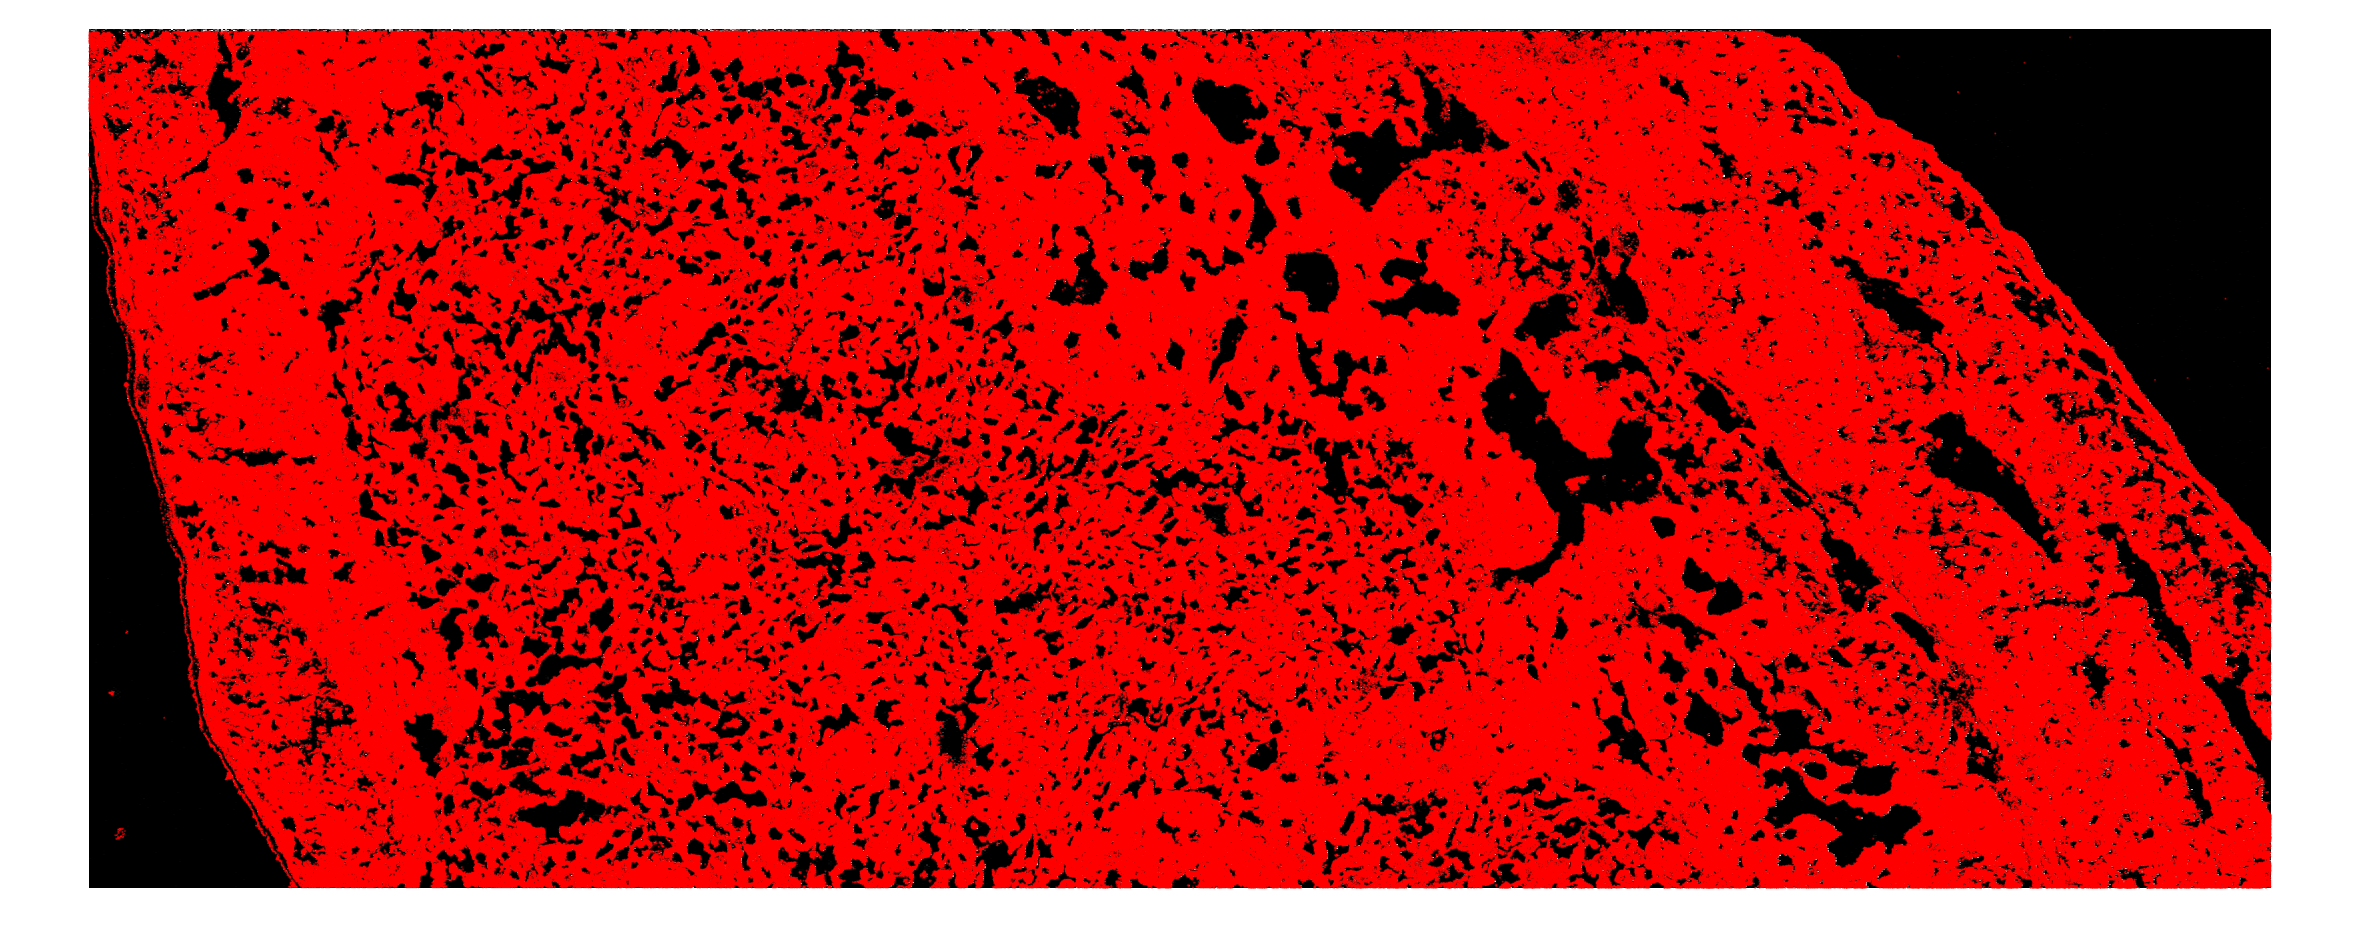

background_file = fullfile("E:/2020-08-01-mPlac/output/max/stitched_images/round1_stitched.tif");
bk_img = imread(background_file);

plot_centroids(merged_points, bk_img, 0.3)

save("E:/2020-08-01-mPlac/output/max/merged_goodPoints_max3d.mat", "merged_points", "merged_reads");